2)

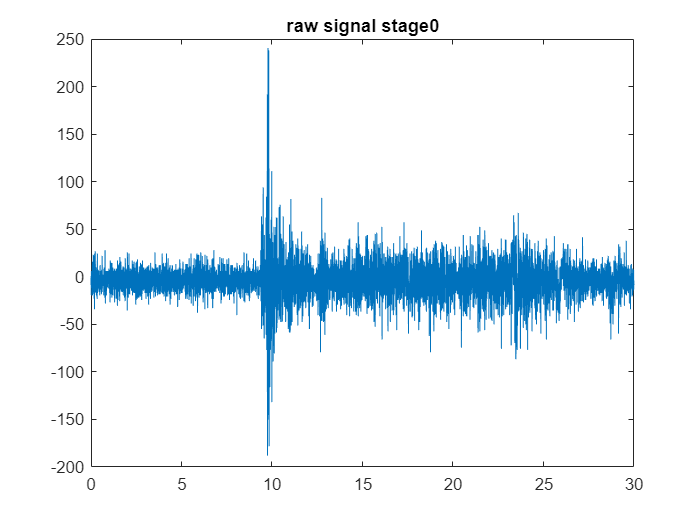

clear
clc
load data.mat
fs=stage0.Fs(3);
t=0:1/fs:(length(stage0.Data(:,3))-1)/fs;
plot(t,stage0.Data(:,3))
title('raw signal stage0')

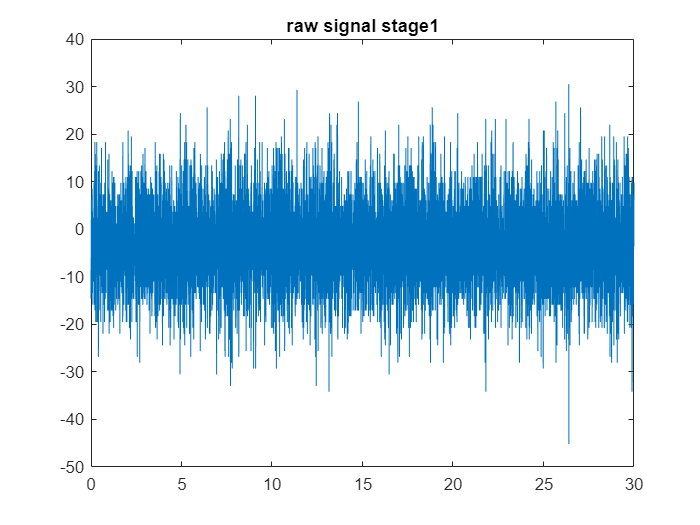

t=0:1/fs:(length(stage1.Data(:,3))-1)/fs;
plot(t,stage1.Data(:,3))
title('raw signal stage1')

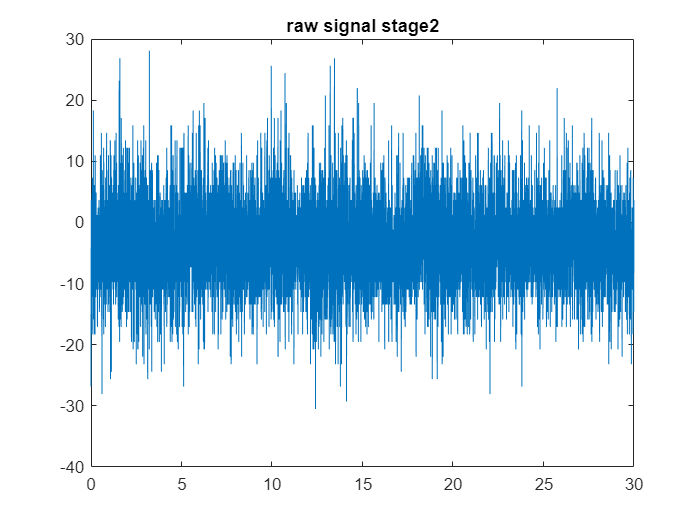

t=0:1/fs:(length(stage2.Data(:,3))-1)/fs;
plot(t,stage2.Data(:,3))
title('raw signal stage2')

3) We take the Fourier transfom of channel 3 of the given signal and then filter it to decompose it to desired frequency bands.two methods are used for extracting Delta band which generate the same result(one is using bandpass filter and other one is manually filtering the frequencies of Fourier transform and taking inverse Fourier transform of it)

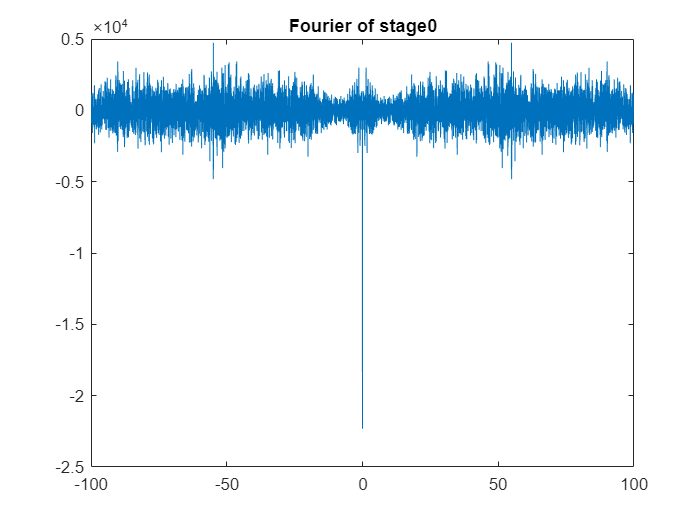

y=fft(stage0.Data(:,3));
y=fftshift(y);
fs=stage0.Fs(3);
oo=length(y);
L=(-oo/2:oo/2-1)*(fs/oo);
t=0:1/fs:(length(stage0.Data(:,3))-1)/fs;
plot(L,real(y))
title('Fourier of stage0')

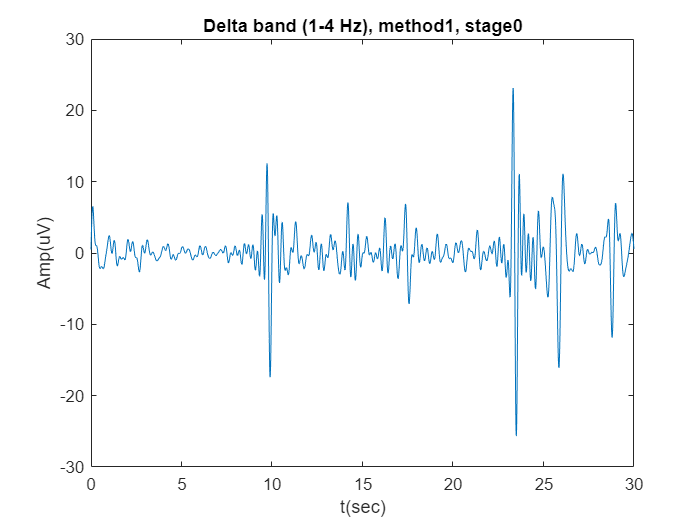


%Delta extraction
delta1=bandpass(stage0.Data(:,3),[1 4],fs); %method1
plot(t,delta1)  
title('Delta band (1-4 Hz), method1, stage0')
xlabel('t(sec)')
ylabel('Amp(uV)')

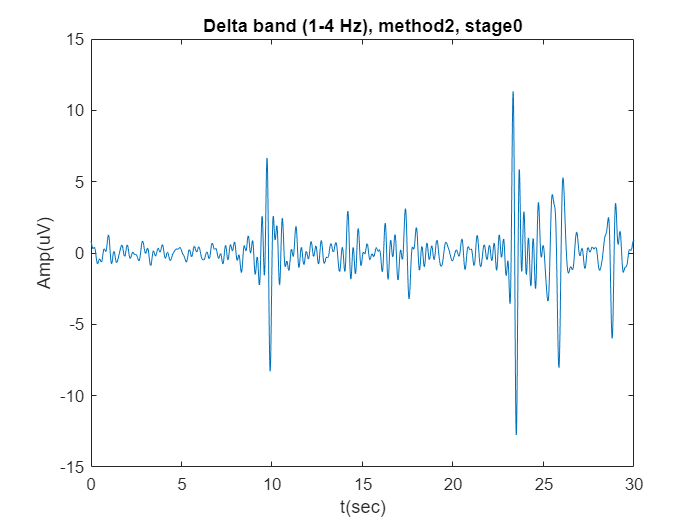

ydelta=y;
ydelta(~(-1<L & L<-4) & ~(L>1 & L<4))=0;    %method2
ydelta=ifftshift(ydelta);
delta=ifft(ydelta);
plot(t,real(delta))
title('Delta band (1-4 Hz), method2, stage0')
xlabel('t(sec)')
ylabel('Amp(uV)')

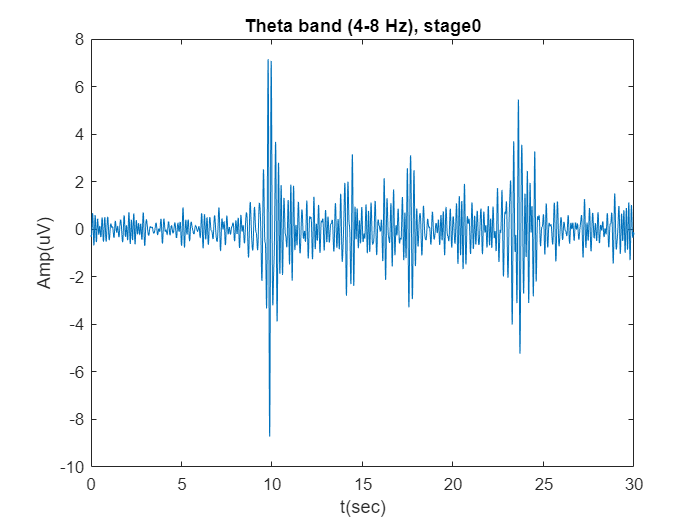

pdelta0=1/length(y)*sum(real(delta).^2);

%Theta extraction
ytheta=y;
ytheta(~(-4<L & L<-8) & ~(L>4 & L<8))=0;  
ytheta=ifftshift(ytheta);
theta=ifft(ytheta);
plot(t,real(theta))
title('Theta band (4-8 Hz), stage0')
xlabel('t(sec)')
ylabel('Amp(uV)')

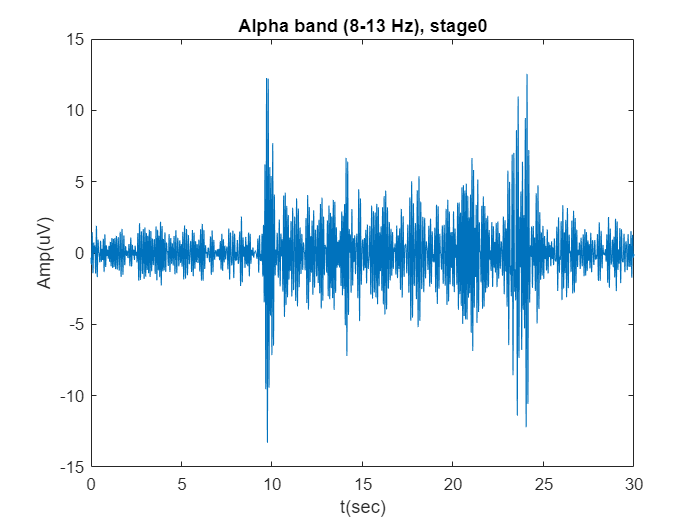

ptheta0=1/length(y)*sum(real(theta).^2);

%Alpha extraction
yalpha=y;
yalpha(~(-13<L & L<-8) & ~(L>8 & L<13))=0;  
yalpha=ifftshift(yalpha);
alpha=ifft(yalpha);
plot(t,real(alpha))
title('Alpha band (8-13 Hz), stage0')
xlabel('t(sec)')
ylabel('Amp(uV)')

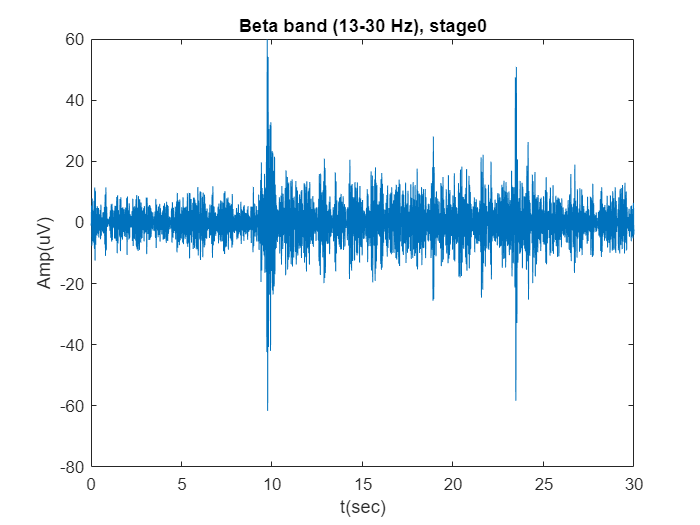

palpha0=1/length(y)*sum(real(alpha).^2);

%Beta extraction
ybeta=y;
ybeta(~(-30<L & L<-13) & ~(L>13 & L<30))=0;  
ybeta=ifftshift(ybeta);
beta=ifft(ybeta);
plot(t,real(beta))
title('Beta band (13-30 Hz), stage0')
xlabel('t(sec)')
ylabel('Amp(uV)')

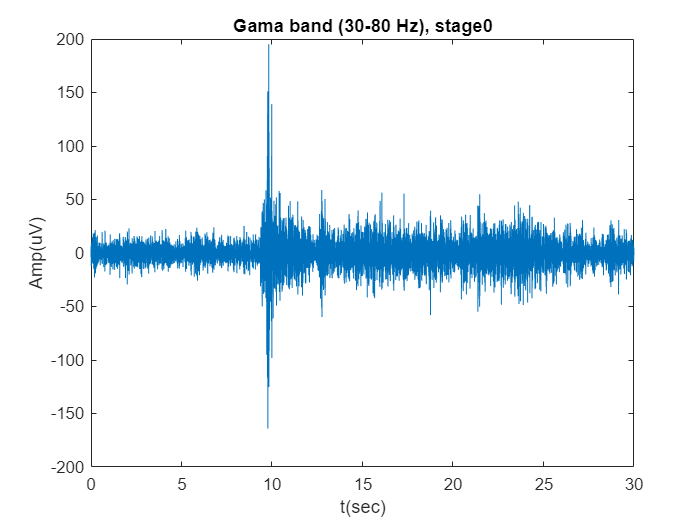

pbeta0=1/length(y)*sum(real(beta).^2);

%Gama extraction
ygama=y;
ygama(~(-80<L & L<-30) & ~(L>30 & L<80))=0;  
ygama=ifftshift(ygama);
gama=ifft(ygama);
plot(t,real(gama))
title('Gama band (30-80 Hz), stage0')
xlabel('t(sec)')
ylabel('Amp(uV)')

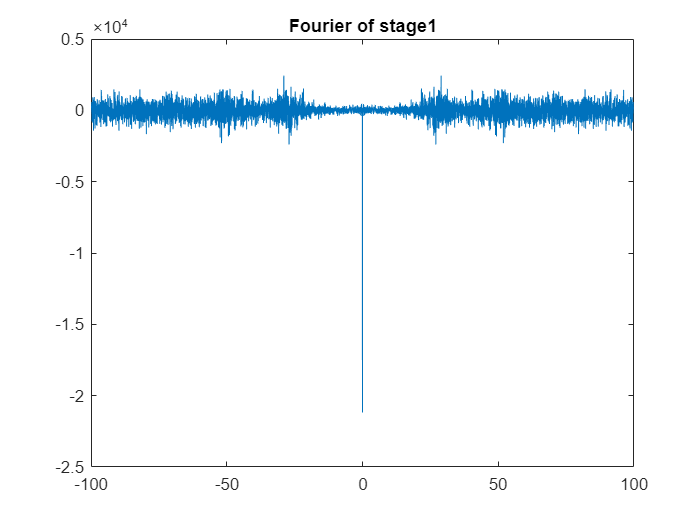

pgama0=1/length(y)*sum(real(gama).^2);

y=fft(stage1.Data(:,3));
y=fftshift(y);
fs=stage1.Fs(3);
oo=length(y);
L=(-oo/2:oo/2-1)*(fs/oo);
t=0:1/fs:(length(stage1.Data(:,3))-1)/fs;
plot(L,real(y))
title('Fourier of stage1')

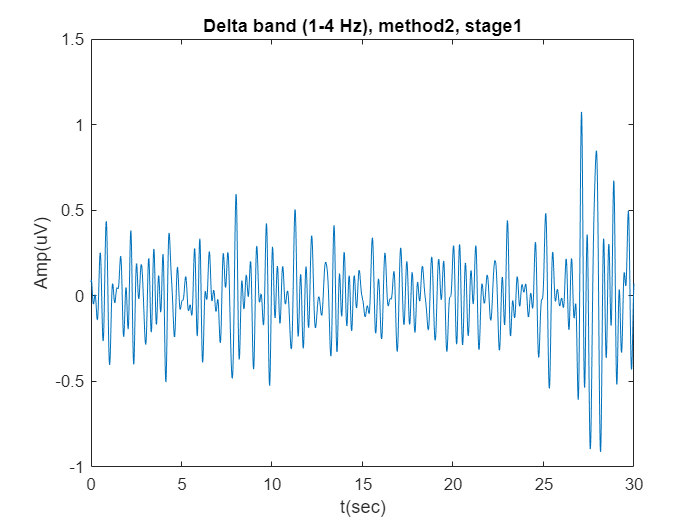


%Delta extraction
ydelta=y;
ydelta(~(-1<L & L<-4) & ~(L>1 & L<4))=0;    %method2
ydelta=ifftshift(ydelta);
delta=ifft(ydelta);
plot(t,real(delta))
title('Delta band (1-4 Hz), method2, stage1')
xlabel('t(sec)')
ylabel('Amp(uV)')

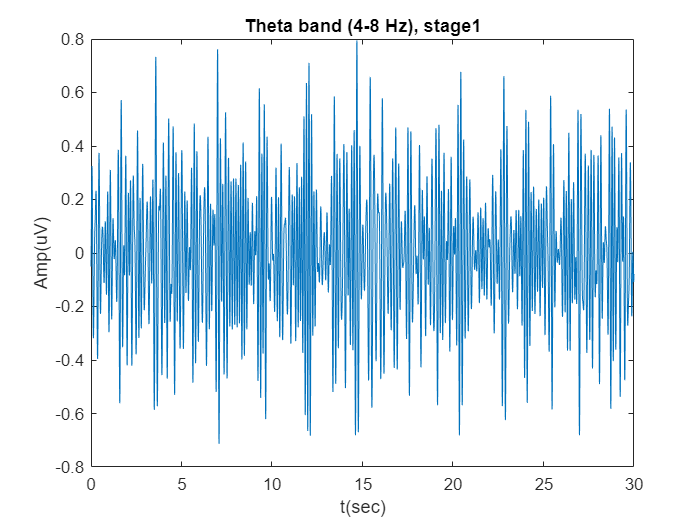

pdelta1=1/length(y)*sum(real(delta).^2);


%Theta extraction
ytheta=y;
ytheta(~(-4<L & L<-8) & ~(L>4 & L<8))=0;  
ytheta=ifftshift(ytheta);
theta=ifft(ytheta);
plot(t,real(theta))
title('Theta band (4-8 Hz), stage1')
xlabel('t(sec)')
ylabel('Amp(uV)')

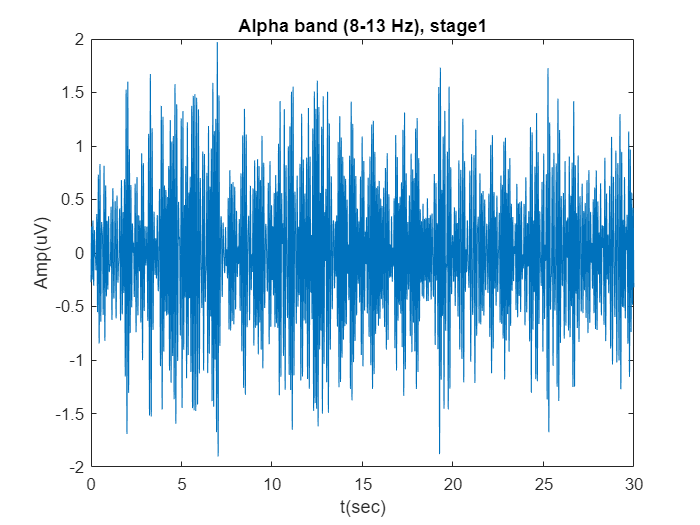

ptheta1=1/length(y)*sum(real(theta).^2);


%Alpha extraction
yalpha=y;
yalpha(~(-13<L & L<-8) & ~(L>8 & L<13))=0;  
yalpha=ifftshift(yalpha);
alpha=ifft(yalpha);
plot(t,real(alpha))
title('Alpha band (8-13 Hz), stage1')
xlabel('t(sec)')
ylabel('Amp(uV)')

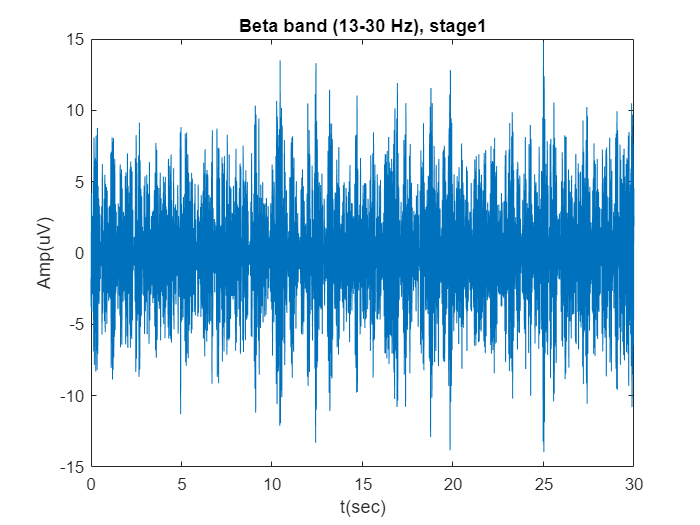

palpha1=1/length(y)*sum(real(alpha).^2);

%Beta extraction
ybeta=y;
ybeta(~(-30<L & L<-13) & ~(L>13 & L<30))=0;  
ybeta=ifftshift(ybeta);
beta=ifft(ybeta);
plot(t,real(beta))
title('Beta band (13-30 Hz), stage1')
xlabel('t(sec)')
ylabel('Amp(uV)')

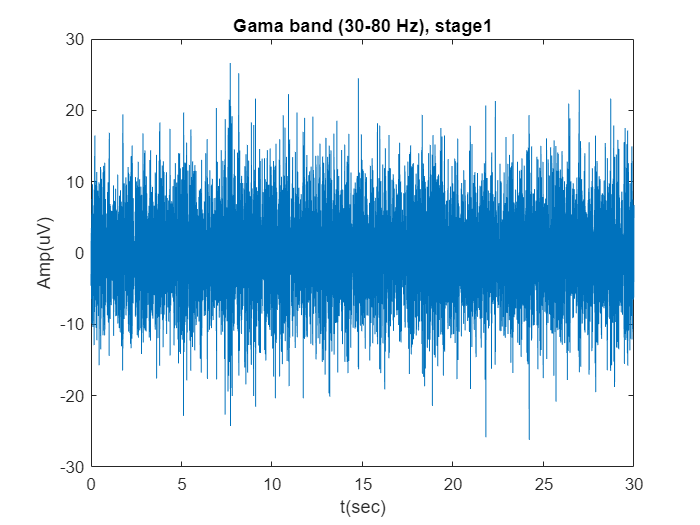

pbeta1=1/length(y)*sum(real(beta).^2);


%Gama extraction
ygama=y;
ygama(~(-80<L & L<-30) & ~(L>30 & L<80))=0;  
ygama=ifftshift(ygama);
gama=ifft(ygama);
plot(t,real(gama))
title('Gama band (30-80 Hz), stage1')
xlabel('t(sec)')
ylabel('Amp(uV)')

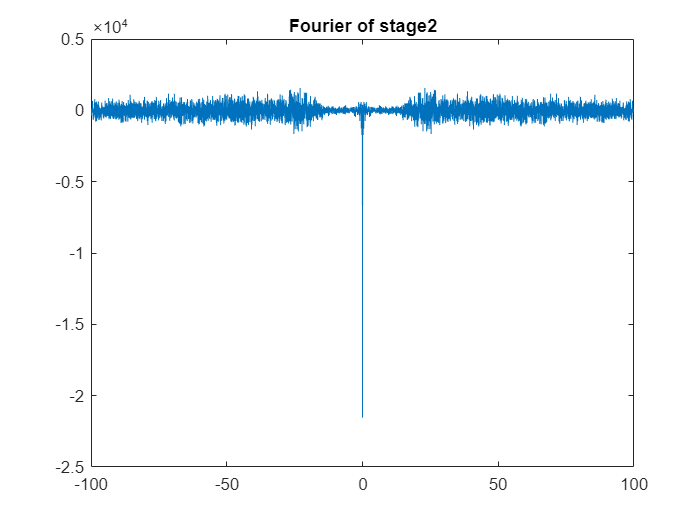

pgama1=1/length(y)*sum(real(gama).^2);


y=fft(stage2.Data(:,3));
y=fftshift(y);
fs=stage2.Fs(3);
oo=length(y);
L=(-oo/2:oo/2-1)*(fs/oo);
t=0:1/fs:(length(stage2.Data(:,3))-1)/fs;
plot(L,real(y))
title('Fourier of stage2')

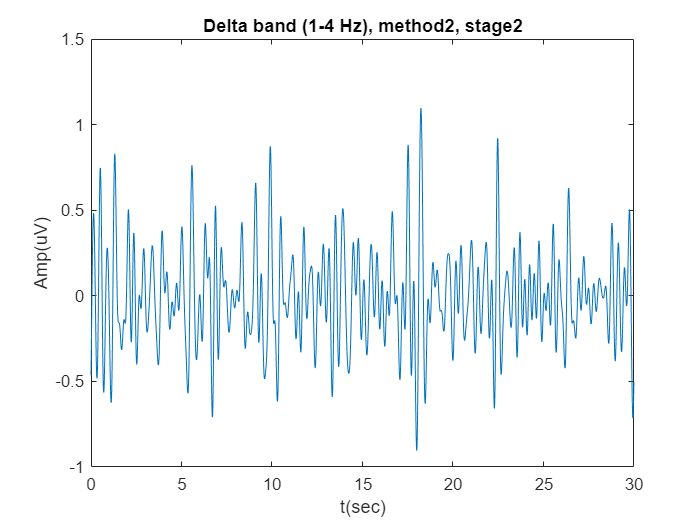


%Delta extraction
ydelta=y;
ydelta(~(-1<L & L<-4) & ~(L>1 & L<4))=0;    %method2
ydelta=ifftshift(ydelta);
delta=ifft(ydelta);
plot(t,real(delta))
title('Delta band (1-4 Hz), method2, stage2')
xlabel('t(sec)')
ylabel('Amp(uV)')

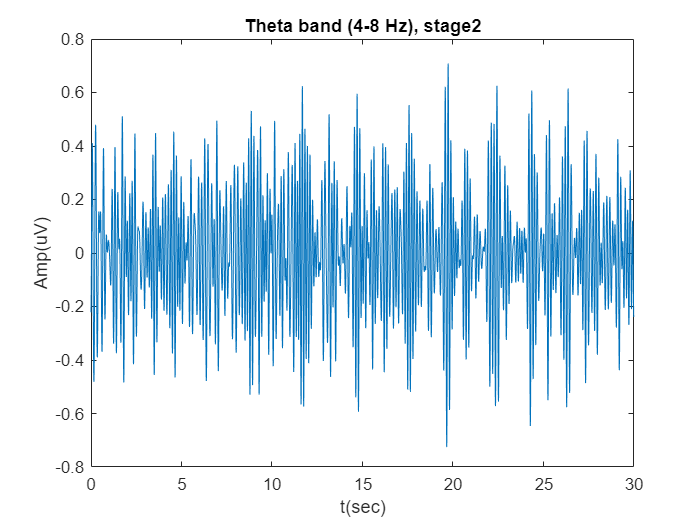

pdelta2=1/length(y)*sum(real(delta).^2);


%Theta extraction
ytheta=y;
ytheta(~(-4<L & L<-8) & ~(L>4 & L<8))=0;  
ytheta=ifftshift(ytheta);
theta=ifft(ytheta);
plot(t,real(theta))
title('Theta band (4-8 Hz), stage2')
xlabel('t(sec)')
ylabel('Amp(uV)')

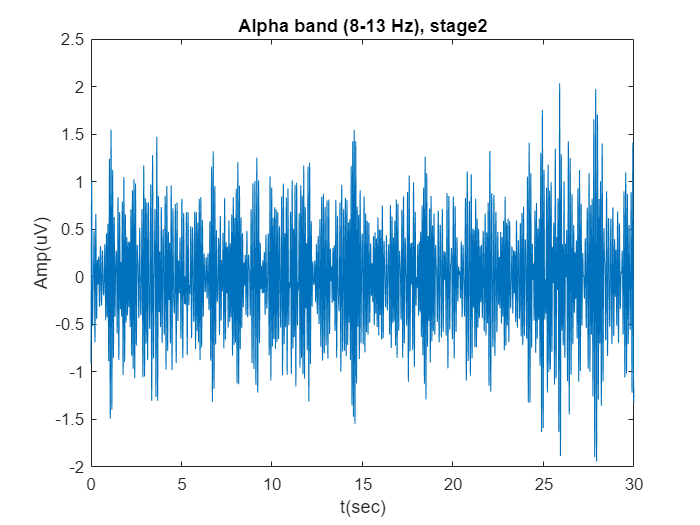

ptheta2=1/length(y)*sum(real(theta).^2);


%Alpha extraction
yalpha=y;
yalpha(~(-13<L & L<-8) & ~(L>8 & L<13))=0;  
yalpha=ifftshift(yalpha);
alpha=ifft(yalpha);
plot(t,real(alpha))
title('Alpha band (8-13 Hz), stage2')
xlabel('t(sec)')
ylabel('Amp(uV)')

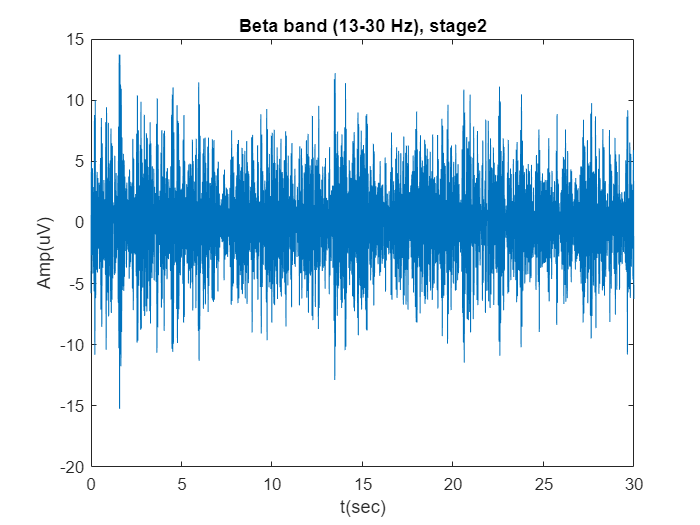

palpha2=1/length(y)*sum(real(alpha).^2);


%Beta extraction
ybeta=y;
ybeta(~(-30<L & L<-13) & ~(L>13 & L<30))=0;  
ybeta=ifftshift(ybeta);
beta=ifft(ybeta);
plot(t,real(beta))
title('Beta band (13-30 Hz), stage2')
xlabel('t(sec)')
ylabel('Amp(uV)')

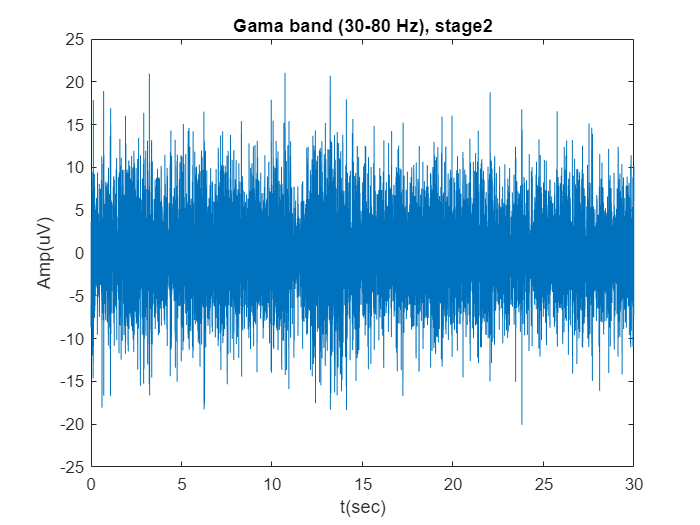

pbeta2=1/length(y)*sum(real(beta).^2);


%Gama extraction
ygama=y;
ygama(~(-80<L & L<-30) & ~(L>30 & L<80))=0;  
ygama=ifftshift(ygama);
gama=ifft(ygama);
plot(t,real(gama))
title('Gama band (30-80 Hz), stage2')
xlabel('t(sec)')
ylabel('Amp(uV)')

pgama2=1/length(y)*sum(real(gama).^2);



We can see that in stage0 the waves are not very periodic and synchronized but in stage 1 and stage 2 waves are more periodic and more synchronized and also have less amplitude than stage 0.

4)

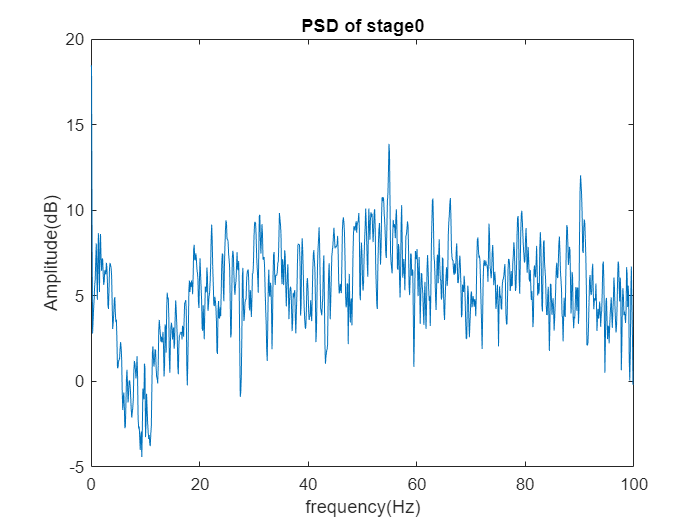

fs0=stage0.Fs(3);
[pxx0,f0]=pwelch(stage0.Data(:,3),[],[],[],fs0);
plot(f0,10*log10(pxx0))
title('PSD of stage0')
xlabel('frequency(Hz)')
ylabel('Amplitude(dB)')

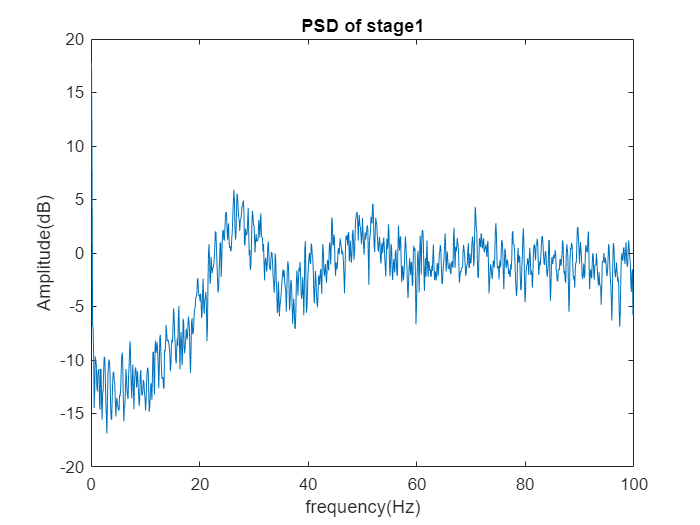


fs1=stage1.Fs(3);
[pxx1,f1]=pwelch(stage1.Data(:,3),[],[],[],fs1);
plot(f1,10*log10(pxx1))
title('PSD of stage1')
xlabel('frequency(Hz)')
ylabel('Amplitude(dB)')

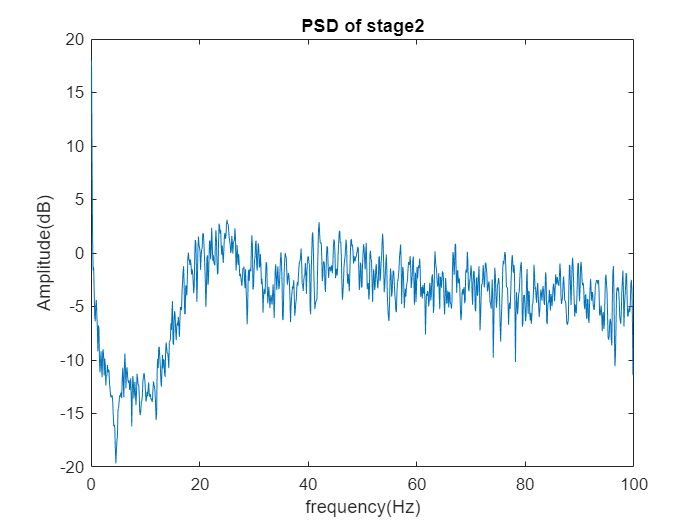


fs2=stage2.Fs(3);
[pxx2,f2]=pwelch(stage2.Data(:,3),[],[],[],fs2);
plot(f2,10*log10(pxx2))
y0=fft(stage0.Data(:,3));
title('PSD of stage2')
xlabel('frequency(Hz)')
ylabel('Amplitude(dB)')

We can see that overall amplitude of stage 0 is much larger than other stages and also amplitude in stage 1 is larger than stage2. in stage 0, Delta waves contribute more to PSD than in stage 1 and stage 2.

5)

pdelta0

pdelta0 = 2.7222

pdelta1

pdelta1 = 0.0484

pdelta2

pdelta2 = 0.0761

ptheta0

ptheta0 = 1.0351

ptheta1

ptheta1 = 0.0608

ptheta2

ptheta2 = 0.0489

palpha0

palpha0 = 4.2092

palpha1

palpha1 = 0.3622

palpha2

palpha2 = 0.3002

pbeta0

pbeta0 = 48.7218

pbeta1

pbeta1 = 15.2563

pbeta2

pbeta2 = 13.3368

pgama0

pgama0 = 216.7052

pgama1

pgama1 = 47.6224

pgama2

pgama2 = 30.8828

From power of each band in each state we can see that power of waves in stage 0 is greater than other two stages, and aslo power of bands in stage 1 is greater than power of stage2, but only power of Delta band in stage2 is greater than power of Delta band in stage 1, also beta and gama waves have higher powers and Delta and theta waves have lowest powers.

also from graphs in part 3, we can see that each band in stage0 has more amplitude than the other 2 and there is 2 peaks in stage 0 which is not is stages 1 and 2, 

6)

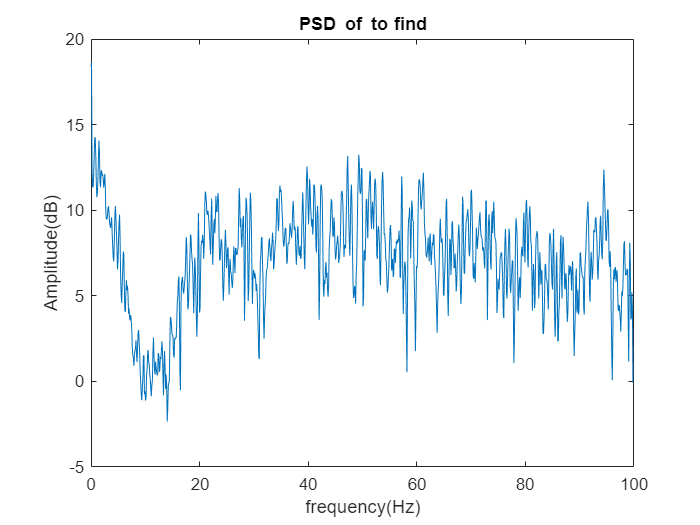

fs3=to_find.Fs(3);
[pxx3,f3]=pwelch(to_find.Data(:,3),[],[],[],fs3);
plot(f3,10*log10(pxx3))
title('PSD of to_ find')
xlabel('frequency(Hz)')
ylabel('Amplitude(dB)')

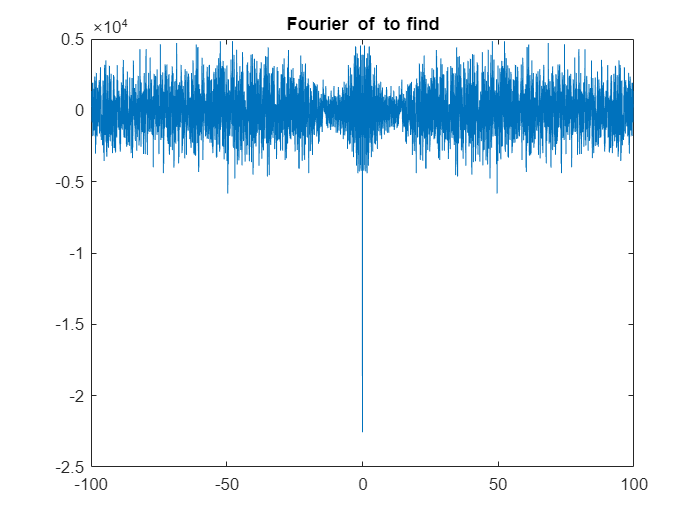

y3=fft(to_find.Data(:,3));
y3=fftshift(y3);
fs=to_find.Fs(3);
oo=length(y3);
L=(-oo/2:oo/2-1)*(fs/oo);
plot(L,real(y3))
title('Fourier of to_ find')

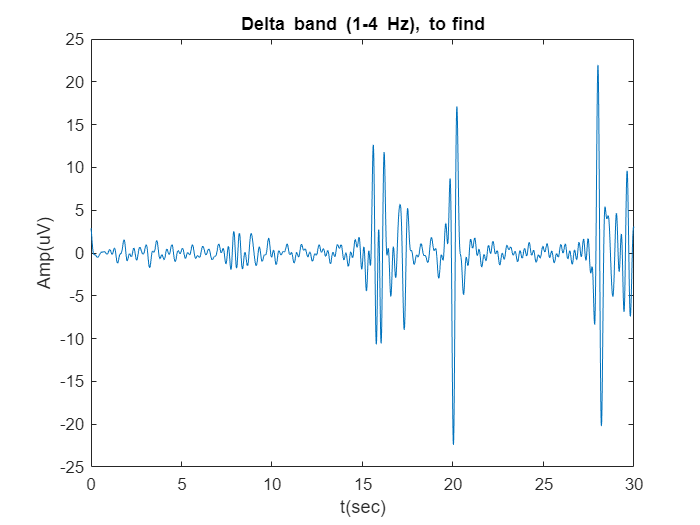


y=fft(to_find.Data(:,3));
y=fftshift(y);
fs=to_find.Fs(3);
oo=length(y);
L=(-oo/2:oo/2-1)*(fs/oo);
t=0:1/fs:(length(to_find.Data(:,3))-1)/fs;
ydelta=y;
ydelta(~(-1<L & L<-4) & ~(L>1 & L<4))=0;    
ydelta=ifftshift(ydelta);
delta=ifft(ydelta);
plot(t,real(delta))
title('Delta band (1-4 Hz), to_ find')
xlabel('t(sec)')
ylabel('Amp(uV)')

pdelta4=1/length(y)*sum(real(delta).^2)

pdelta4 = 10.0994

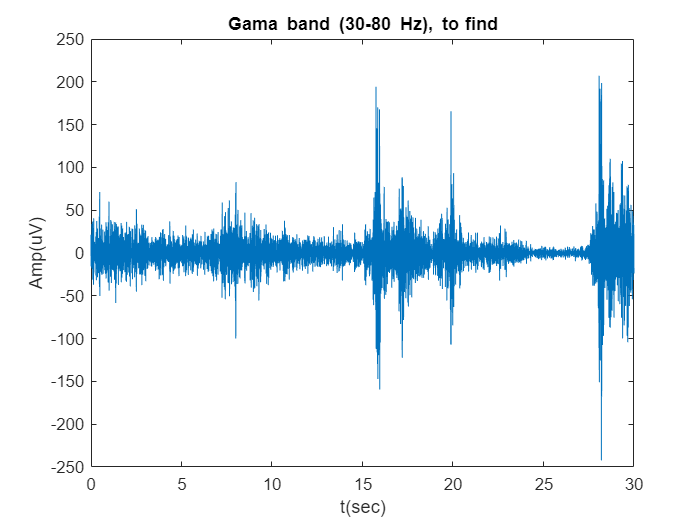


ygama=y;
ygama(~(-80<L & L<-30) & ~(L>30 & L<80))=0;  
ygama=ifftshift(ygama);
gama=ifft(ygama);
plot(t,real(gama))
title('Gama band (30-80 Hz), to_ find')
xlabel('t(sec)')
ylabel('Amp(uV)')

pgama4=1/length(y)*sum(real(gama).^2)

pgama4 = 444.0717

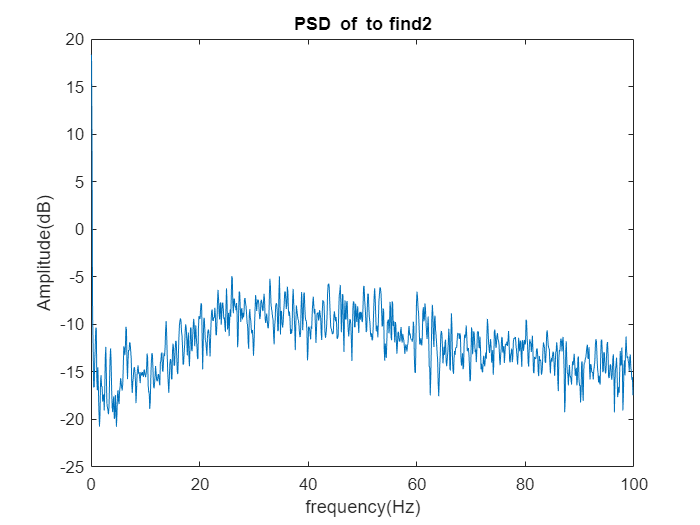


fs4=to_find2.Fs(3);
[pxx4,f4]=pwelch(to_find2.Data(:,3),[],[],[],fs4);
plot(f4,10*log10(pxx4))
title('PSD of to_ find2')
xlabel('frequency(Hz)')
ylabel('Amplitude(dB)')

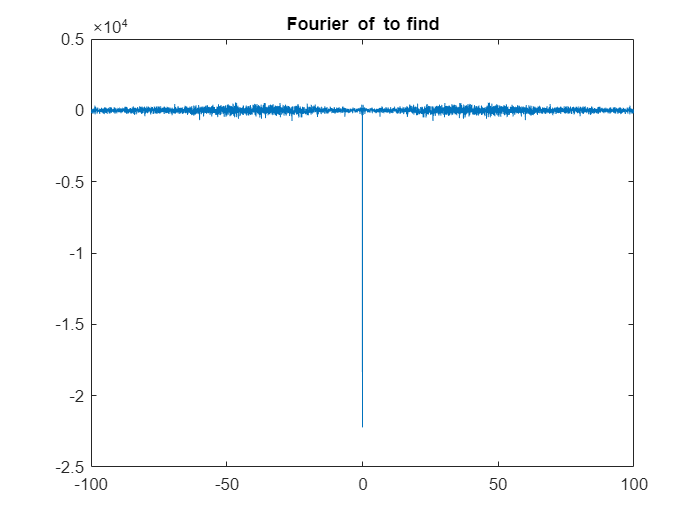

y4=fft(to_find2.Data(:,3));
y4=fftshift(y4);
fs=to_find2.Fs(3);
oo=length(y4);
L=(-oo/2:oo/2-1)*(fs/oo);
plot(L,real(y4))
title('Fourier of to_ find')

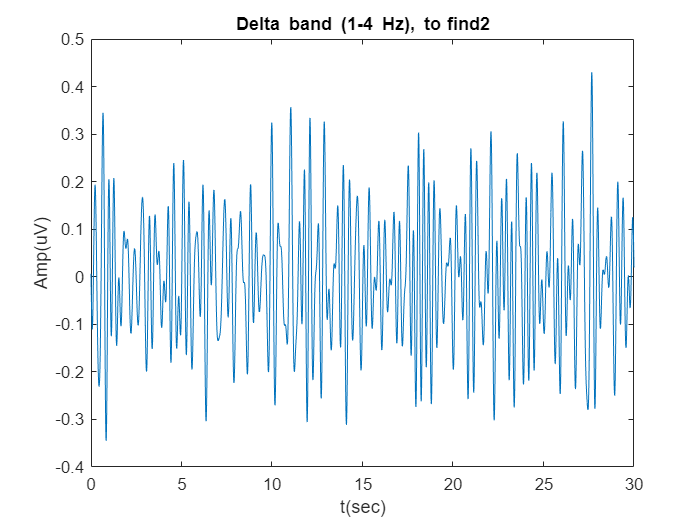


y=fft(to_find2.Data(:,3));
y=fftshift(y);
fs=to_find2.Fs(3);
oo=length(y);
L=(-oo/2:oo/2-1)*(fs/oo);
t=0:1/fs:(length(to_find2.Data(:,3))-1)/fs;
ydelta=y;
ydelta(~(-1<L & L<-4) & ~(L>1 & L<4))=0;    %method2
ydelta=ifftshift(ydelta);
delta=ifft(ydelta);
plot(t,real(delta))
title('Delta band (1-4 Hz), to_ find2')
xlabel('t(sec)')
ylabel('Amp(uV)')

pdelta5=1/length(y)*sum(real(delta).^2)

pdelta5 = 0.0170

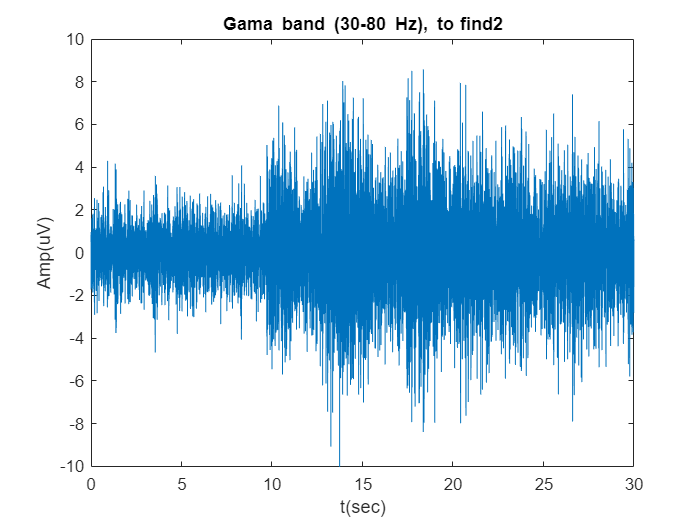

ygama=y;
ygama(~(-80<L & L<-30) & ~(L>30 & L<80))=0;  
ygama=ifftshift(ygama);
gama=ifft(ygama);
plot(t,real(gama))
title('Gama band (30-80 Hz), to_ find2')
xlabel('t(sec)')
ylabel('Amp(uV)')

pgama5=1/length(y)*sum(real(gama).^2)

pgama5 = 4.7255

From comparing psd, Delta and Gama waves, power of Delta and Gama bands and Fourier transform of to_find data with known data we can see that to_find is similar to stage 0, and to_find2 is more similar to stage 2